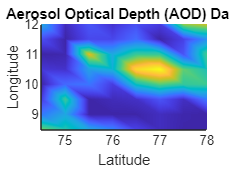

import matlab.io.hdf4.*
import matlab.io.hdfeos.*

% Specify the directory containing your HDF files
directory = 'F:/Internship IITM/Jan/';

% Get a list of all HDF files in the directory
folder = dir(fullfile(directory, '*.hdf'));

%lat_grid = 0:2:20;
%lon_grid = 65:2:85;

% Define latitude and longitude grid for Kerala region
lat_min = 8;   % Minimum latitude of Kerala region
lat_max = 12;  % Maximum latitude of Kerala region
lon_min = 74;  % Minimum longitude of Kerala region
lon_max = 78;  % Maximum longitude of Kerala region
lat_grid = lat_min:0.5:lat_max;
lon_grid = lon_min:0.5:lon_max;

% Initialize grid matrix for AOD data
grid_mat = zeros(length(lon_grid)-1, length(lat_grid)-1);

% Loop through each HDF file
for n = 1:length(folder)
    FILENAME = fullfile(directory, folder(n).name);
    
    % Open the HDF file
    file_id = gd.open(FILENAME, 'rdonly');


    % Read latitude and longitude data
    GRID_NAME='grid1km';
    grid_id = gd.attach(file_id, GRID_NAME);

    DATAFIELD_NAME='Optical_Depth_055';
    [AOD, lat, lon] = gd.readField(grid_id, DATAFIELD_NAME, [], [], []);

   
    % Close the file.
    gd.close(file_id);

    % Convert Latitude and Longitude to double and scale
    AOD=squeeze(AOD(:,:,1));
    AOD(AOD<0)=NaN;
    AOD=double(AOD).*0.001;
    
    Latitude = double(lat);
    Longitude = double(lon); 

    % Loop through grid cells

    for k = 1:length(lon_grid)-1
        for j = 1:length(lat_grid)-1
           % Find indices within grid cell
           indices = find(Longitude > lon_grid(k) & Longitude <= lon_grid(k+1) & Latitude > lat_grid(j) & Latitude <= lat_grid(j+1) );
           if ~isempty(indices)
               % Calculate mean of AOD values within grid cell
              grid_mat(k,j) = mean(AOD(indices), 'omitnan');
           end
        end
    end
end

% Plot the AOD data
figure;
pcolor(lon_grid(2:end), lat_grid(2:end),grid_mat); 
shading interp;
xlabel('Latitude');
ylabel('Longitude');
title('Aerosol Optical Depth (AOD) Data');